clc; clear all; close all;

% Definición del sistema (Planta)
A = [0 1; -3 -5];
B = [0; 1];
C = [1 0];
D = [0];

% Parámetros del MPC
Ts = 0.2;         % Tiempo de muestreo
N = 50;            % Horizonte de predicción
Qy = 100;         % Penalización de la salida
R = 0.1;          % Penalización del control
yref = 1;         % Referencia deseada
x0 = [0; 0];      % Estado inicial


constraints.Umax = 10;   
constraints.Umin = -1;  
constraints.Xmax = [2; 2]; 
constraints.Xmin = [-5; -5]; 

% Llamada a la función MPC
[X, U] = mpc_controller(A, B, C, D, Ts, N, Qy, R, yref, x0);

Ad =     0.9563    0.1240
   -0.3719    0.3365


Bd =     0.0146
    0.1240


Qbig =    100     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0   100     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

q =   -100
     0
  -100
     0
  -100
     0
  -100
     0
  -100
     0


Aeq =    -1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

beq =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


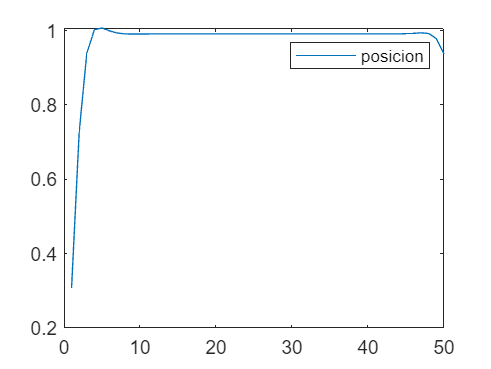


plot(X(1:2:end));  
legend('posicion')

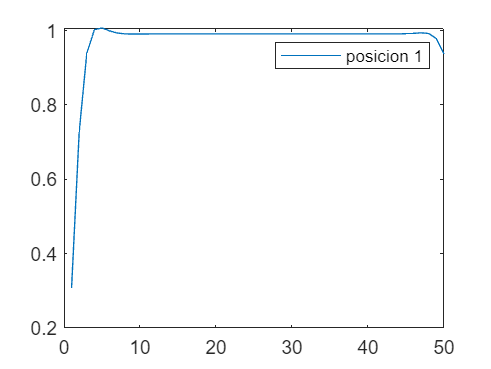


figure
plot(X(1 , :));
legend('posicion 1')

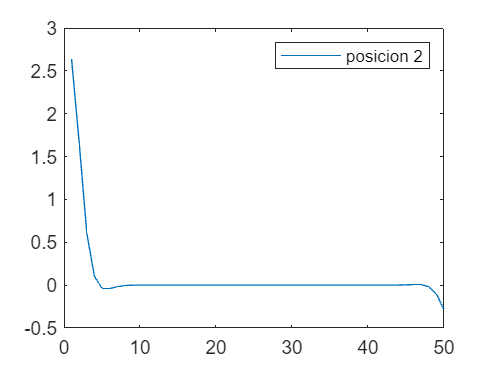


figure
plot(X(2 , :));
legend('posicion 2')

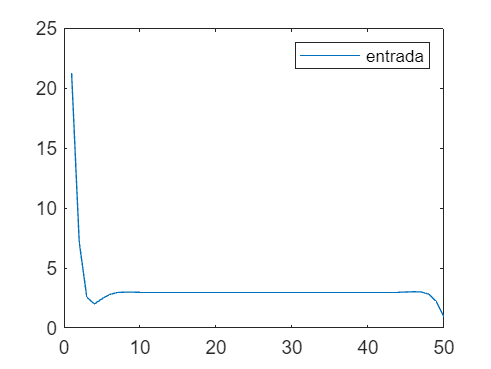


figure
plot(U)
legend('entrada')

function [X, U] = mpc_controller(A, B, C, D, Ts, N, Qy, R, yref, x0, constraints)
    % ZOH
    sysc = ss(A, B, C, D);
    sysd = c2d(sysc, Ts, 'zoh');
    Ad = sysd.A
    Bd = sysd.B
 
    % Ad=A*Ts+eye(size(A))
    % Bd=B*Ts

    % Función de costo
    Qbig = blkdiag(kron(eye(N), C' * Qy * C), kron(eye(N), R))
    q = repmat(-C' * Qy * yref, N, 1);
    q = [q; zeros(N, 1)] % Para la parte de U

    % Restricciones de igualdad 
    nx = size(A, 1); % ---->  Número de estados
    nu = size(B, 2); % ----> Número de entradas

    Aeq = zeros(N * nx, N * (nx + nu));
    beq = zeros(N * nx, 1);

    for k = 1:N
        Aeq((k-1)*nx+1:k*nx, (k-1)*nx+1:k*nx) = -eye(nx);
        if k == 1
            Aeq(1:nx, 1:nx) = -eye(nx);
            Aeq(1:nx, nx*N+1:nx*N+nu) = Bd;
            beq(1:nx) = -Ad * x0;
        else
            Aeq((k-1)*nx+1:k*nx, (k-2)*nx+1:(k-1)*nx) = Ad;
            Aeq((k-1)*nx+1:k*nx, nx*N+(k-1)*nu+1:nx*N+k*nu) = Bd;
        end
    end
    % Restricciones 
    Aineq = [];
    bineq = [];
    if nargin == 11 && ~isempty(constraints)
        if isfield(constraints, 'Umax') && isfield(constraints, 'Umin')
            Aineq = [Aineq; kron(eye(N), [zeros(nu, nx), eye(nu)]); 
                             kron(eye(N), [zeros(nu, nx), -eye(nu)])];
            bineq = [bineq; repmat(constraints.Umax, N, 1); 
                              repmat(-constraints.Umin, N, 1)];
        end
        if isfield(constraints, 'Xmax') && isfield(constraints, 'Xmin')
            Aineq = [Aineq; kron(eye(N), [eye(nx), zeros(nx, nu)]); 
                             kron(eye(N), [-eye(nx), zeros(nx, nu)])];
            bineq = [bineq; repmat(constraints.Xmax, N, 1); 
                              repmat(-constraints.Xmin, N, 1)];
        end
    end
    Aeq
    beq

    if isempty(Aineq)
        z = quadprog(Qbig, q, [], [], Aeq, beq);
    else
        z = quadprog(Qbig, q, Aineq, bineq, Aeq, beq);
    end

    X = reshape(z(1:N*nx), nx, N);
    U = z(N*nx+1:end);    
end
